## Boas Práticas

clear all;
close all
clc;

## Leitura do arquivo .wav - audioread


[Y, FS] = audioread('Audio02.wav')

Y =    -0.0022
   -0.0021
   -0.0019
   -0.0018
   -0.0018
   -0.0017
   -0.0017
   -0.0019
   -0.0020
   -0.0021


FS = 44100

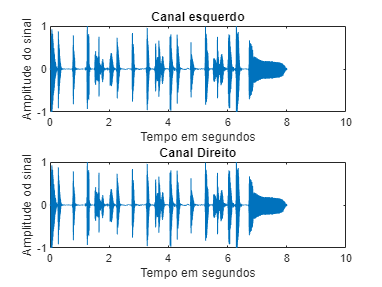

% Y é a amplitude, e FS é a frequencia do sinal lido


TS = 1/FS;
Npontos = length(Y);
Vfinal = (Npontos-1)*TS;

tempo = linspace(0,Vfinal,Npontos);

figure(1);

subplot(2,1,1)
plot(tempo, Y(:,1))
xlabel("Tempo em segundos")
ylabel("Amplitude do sinal")
title("Canal esquerdo")
subplot(2,1,2)
plot(tempo,Y(:))
xlabel("Tempo em segundos")
ylabel("Amplitude od sinal")
title("Canal Direito")

## Ouvir um arquivo .wav

%sound(Y,FS);

## FFT foda


FY = fftshift(fft(Y));

## Visualizar o FFT

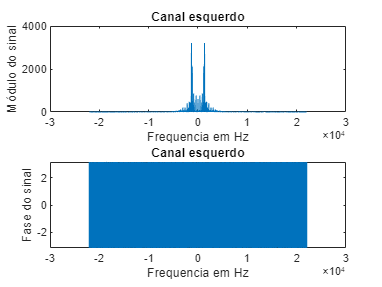

frequencia = linspace(-FS/2,FS/2,Npontos);

figure(2)

subplot(2,1,1)
plot(frequencia,abs(FY(:,1)))
xlabel("Frequencia em Hz")
ylabel("Módulo do sinal")
title("Canal esquerdo")

subplot(2,1,2)
plot(frequencia,angle(FY(:,1)))
xlabel("Frequencia em Hz")
ylabel("Fase do sinal")
title("Canal esquerdo")


% subplot(2,1,1)
% xlim([-3000, 3000])
% ylim([24 7400])